# 1. Introducción a MATLAB

#### Autor: German Preciat

#### Contacto: gapreciat@gmail.com

MATLAB es el nombre abreviado de “MATriz LABoratory”. Es un programa para realizar cálculos numéricos con vectores y matrices, y por tanto se puede trabajar también con números escalares (tanto reales como complejos), con cadenas de caracteres y con otras estructuras de información más complejas. 

Matlab es un lenguaje de alto rendimiento para cálculos técnicos, es al mismo tiempo un entorno y un lenguaje de programación. Uno de sus puntos fuertes es que permite construir nuestras propias herramientas reutilizables. Podemos crear fácilmente nuestras propias funciones y programas especiales (conocidos como M-archivos) en código Matlab, los podemos agrupar en Toolbox (también llamadas librerías): colección especializada de M-archivos para trabajar en clases particulares de problemas. 

Matlab, a parte del cálculo matricial y álgebra lineal, también puede manejar polinomios, funciones, ecuaciones diferenciales ordinarias, gráficos … 

El propósito de esta práctica es conocer algunas de las funciones básicas de `MATLAB`.

## 01. Operaciones **básicas **y **declaración **de variables

Las operaciones se pueden hacer desde la ventana de comando o en el "Live Editor".

2 + 45 % Suma

ans =     47


52 - 44 % Resta

ans =      8


4 * 12 % Multiplicación

ans =     48


225 / 15 % División

ans =     15


8^2 % Potencias

ans =     64


sqrt(81) % Raíz cuadrada

ans =      9


(12 + 2) * 4 % Paréntesis

ans =     56


12 + (2 * 4)

ans =     20


1 > 20 % Desigualdades (resultado en verdadero (1) o falso (0))

ans = logical
   0


20 == 20

ans = logical
   1


8 <= 20

ans = logical
   1


1:10 % Series con intervalo de una unidad

ans =      1     2     3     4     5     6     7     8     9    10


1:2:7 % Series con intervalo de 2 unidades

ans =      1     3     5     7


5:-1:1 % Series con intervalo de -1 unidades

ans =      5     4     3     2     1


Un número, un vector, una matriz o el resultado de una operación pueden ser salvados en variables las cuales no pueden comenzar con números o símbolos. Los vectores y matrices se definen entre corchetes (`[]`) añadiendo un punto y coma (`;`) para indicar cada nuevo renglón. Adicionalmente, el punto y coma (`;`) al final de un comando evita que el resultado se imprima en la ventana de comandos.

a = 12; 
b = a * 2;
v1 = [1; 2]; % Vector de 2x1
v2 = 1:3; % Vector de 1x3
M1 = [1 2 3 4; 5 6 7 8]; % Matriz de 2x4
M2 = [1 2 3; 4 5 6; 7 8 9] % Matriz de 3x3 (sin el punto y coma se imprime el resultado)

M2 =      1     2     3
     4     5     6
     7     8     9


Para conocer las dimensiones de un vector se utilizan diferentes funciones como:

- `numel`: Indica el número de elementos en la variable

- `length`: Indica la dimensión de la variable

- `size`: Indica las dimensiones de las variables

numel(M1) % Número de elementos en la matriz o vector

ans =      8


length(M1) % Máxima dimensión de la matriz o vector

ans =      4


size(M1) % Dimensiones de la matriz o vector

ans =      2     4


size(M1, 1) % Número de filas 

ans =      2


size(M1, 2) % Número de columnas

ans =      4


Consultar a la ayuda de MATLAB para saber más de todas las funciones. La ayuda se puede consultar en el signo de interrogación (?) en la parte superior derecha de la ventana o usando `help` en la ventana de comandos.

help size

 size   Size of array.  
    D = size(X), for M-by-N matrix X, returns the two-element row vector
    D = [M,N] containing the number of rows and columns in the matrix.
    For N-D arrays, size(X) returns a 1-by-N vector of dimension lengths.
    Trailing singleton dimensions are ignored.
 
    [M,N] = size(X) for matrix X, returns the number of rows and columns in
    X as separate output variables. 
    
    [M1,M2,M3,...,MN] = size(X) for N>1 returns the sizes of the first N 
    dimensions of the array X.  If the number of output arguments N does
    not equal NDIMS(X), then for:
 
    N > NDIMS(X), size returns ones in the "extra" variables, i.e., outputs
                  NDIMS(X)+1 through N.
    N < NDIMS(X), MN contains the product of the sizes of dimensions N
                  through NDIMS(X).
 
    M = size(X,DIM) returns the lengths of the specified dimens

## 02. **Operación **entre vectores y matrices

Para realizar operaciones entre vectores y matrices se deben de tomar en cuenta sus dimensiones. El carácter (`'`) es utilizado para trasponer una matriz o un vector.

v1 

v1 =      1
     2


v2

v2 =      1     2     3


v3 = v2' % Trasponer vector

v3 =      1
     2
     3


v4 = v3 * a % Multiplicación de vector por constante

v4 =     12
    24
    36


M3 = M1' % Trasponer matriz

M3 =      1     5
     2     6
     3     7
     4     8


M4 = v1 * v2 % Multiplicación de vectores

M4 =      1     2     3
     2     4     6


M5 = M4 * b % Multiplicación de matriz por constante

M5 =     24    48    72
    48    96   144


M6 = [M2 v3] % Añadir una columna a una matriz

M6 =      1     2     3     1
     4     5     6     2
     7     8     9     3


Para acceder a valores específicos dentro de un vector o una matriz, las coordenadas deben declarase dentro de un paréntesis. Los dos puntos (`:`) se utilizan para indicar a todos los valores de la dimensión señalada. El comando `end`, se utiliza para señala el fin del vector.

v1(1)

ans =      1


v4(end)

ans =     36


M1(1, 1)

ans =      1


M3(4, 2)

ans =      8


M4(1, :) % Todos los valores de la columna 1 en M4

ans =      1     2     3


M5(:, 3) % Todos los valores de la fila 4 en M5

ans =     72
   144


M6(2:end, 2:3) % Matriz de 2x2 dentro de M6

ans =      5     6
     8     9


## 03. Strings y arreglos

Los arreglos de `MATLAB` pueden contener tanto números como texto, definidas como strings. Un string debe estar definidos entre comillas simples (`'`) para ser reconocidos como texto. Para unir 2 strings pueden usar funciones como `strcat`, que concatena los textos o agregando las variables de texto entre corchetes (`[]`). 

Hay distintos tipos de arreglos:

- Arreglos en celdas

- Arreglos de estructuras

- Tablas

Los arreglos en celdas se declaran utilizando las llaves (`{}`) y tienen una estructura similar a matrices. Una variable numérica puede agregarse como texto al tipo de dato usando la funcion `num2str`. Los arreglos en celdas son útiles para exportar información.

str1 = 'Que onda';
str2 = ' mundo!';
strcat(str1, str2) % Concatenar

ans = 'Que onda mundo!'

str3 = [str1 str2 ' todo bien?'] % Concatenar (otro metodo)

str3 = 'Que onda mundo! todo bien?'

str4 = 'Este es el numero 2';
str5 = ['Y este es el numero ' num2str(a)];
array1 = {str4; str5} % El punto y coma indica una nueva línea

array1 = 2×1 cell array
    {'Este es el numero 2'   }
    {'Y este es el numero 12'}


array2 = {'Dos', 2, '2'; 'Doce', a, num2str(a)} % Un arreglo con diferentes tipos de datos

array2 = 2×3 cell array
    {'Dos' }    {[ 2]}    {'2' }
    {'Doce'}    {[12]}    {'12'}


Las tablas pueden generarse con la función `array2table`, la cual transforma un arreglo en una tabla. 

t1 = array2table(array2)

t1 = 2×3 table
    array21     array22    array23
    ________    _______    _______

    {'Dos' }    {[ 2]}     {'2' } 
    {'Doce'}    {[12]}     {'12'} 


newNames = {'strLetra', 'numero', 'strNumero'};
t1.Properties.VariableNames = newNames

t1 = 2×3 table
    strLetra    numero    strNumero
    ________    ______    _________

    {'Dos' }    {[ 2]}     {'2' }  
    {'Doce'}    {[12]}     {'12'}  


t2 = table;
t2.cellLines = {'Linea1'; 'Linea2'; 'Linea3'};
t2.noOfCells = (2:5:12)';
t2.atpProduction = v3

t2 = 3×3 table
    cellLines     noOfCells    atpProduction
    __________    _________    _____________

    {'Linea1'}        2              1      
    {'Linea2'}        7              2      
    {'Linea3'}       12              3      


Los arreglos de estructura pueden utilizarse para guardar datos de forma estructurada en diferentes campos que a su vez pueden albergar más campos. Los arreglos de estructura tienen una forma similar a las tablas, cada campo es señalado con un punto (`.`).

sa1 = struct;
sa1.vector = v1;
sa1.matrix = M1;
sa1.string = str1;
sa1.array = array1;
sa1.table = t2;
sa1

sa1 = struct with fields:
    vector: [2×1 double]
    matrix: [2×4 double]
    string: 'Que onda'
     array: {2×1 cell}
     table: [3×3 table]


% Nuevo struct array
sa2.vectors.v1 = v1;
sa2.vectors.v2 = v1 + 1;
sa2.matrices.M1 = M1;
sa2.matrices.M2 = M1 * 2;
sa2

sa2 = struct with fields:
     vectors: [1×1 struct]
    matrices: [1×1 struct]


sa2.vectors

ans = struct with fields:
    v1: [2×1 double]
    v2: [2×1 double]


sa2.vectors.v1

ans =      1
     2


sa2.vectors.v1(2)

ans =      2


## 04. Figuras

Matlab cuenta con una variedad de funciones para visualizar datos, algunos ejemplos son:

- `plot`

- `bar`

- `scatter`

- `heatmap`

El comando `hold on` se usa para sobreponer una o más graficas en una misma figura. Para dejar de sobreponer graficas se ejecuta el comando `hold off`. Adicionalmente, `MATLAB` cuenta con diferentes funciones para personalizar una figura, como agregar título, nombre a los ejes, color de la gráfica, ancho de la gráfica, leyenda, etc.

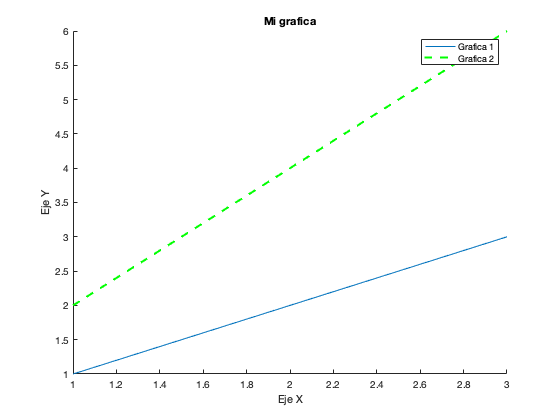

figure
hold on
plot(v2, v3)
plot(v2, v3 * 2, 'g', 'LineWidth', 2, 'LineStyle','--')
title('Mi grafica')
xlabel('Eje X')
ylabel('Eje Y')
legend({'Grafica 1', 'Grafica 2'})
hold off

Además, con la función `subplot`, es posible de agrupar diferentes figuras para su visualización. Se ejecuta como `subfigure(noDefilas, noDecolumnas, noDeFigura)`. 

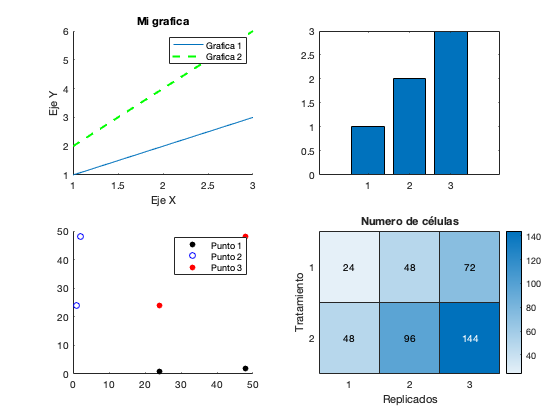

figure
% plot
subplot(2, 2, 1)
hold on
plot(v2, v3)
plot(v2, v3 * 2, 'g', 'LineWidth', 2, 'LineStyle','--')
title('Mi grafica')
xlabel('Eje X')
ylabel('Eje Y')
legend({'Grafica 1', 'Grafica 2'})
hold off

% bar
subplot(2, 2, 2)
bar(v2)

% scatter
subplot(2, 2, 3)
hold on
scatter(M5(:, 1), M4(:, 1), 'black', 'filled')
scatter(M4(:, 1), M5(:, 1), 'blue')
scatter(M5(:, 1), M5(:, 1), 'red', 'filled')
legend({'Punto 1', 'Punto 2', 'Punto 3'})
hold off

% heatmap
subplot(2, 2, 4)
heatmap(M5);
title('Numero de células')
xlabel('Replicados')
ylabel('Tratamiento')

Para saber más de todas las características de las figuras consultar la ayuda de `MATLAB`.

## 05. Estructuras de control

En lenguajes de programación, las **estructuras de control** permiten modificar el flujo de ejecución de las instrucciones de un programa.

Con las estructuras de control se puede:

- De acuerdo con una condición, ejecutar un grupo u otro de sentencias (If-Else)

- Ejecutar un grupo de sentencias un número determinado de veces (For)

- De acuerdo con el valor de una variable, ejecutar un grupo u otro de sentencias (Switch-Case)

- Ejecutar un grupo de sentencias **solo cuando** se cumpla una condición (While)

A continuación, algunos ejemplos de su uso.

### IF

Si `a` es mayor que 32 la variable `c` será igual a la variable `a`, sino será igual a 32.

if a > 32 
    c = a;
else
    c = 32;
end
c

c =     32


### FOR

Crear una matriz que al sumarla con M4 todos los valores sean igual a 12. 

Con la función `zeros` es posible generar un vector o matriz con las dimensiones definidas por el usuario. Otras funciones que se usan de forma similar son `one` (crea una matriz o vector con las dimensiones indicadas) o `cell` (crea celdas vacías con las dimensiones indicadas).

% Conocer las dimensiones de M4
[m, n] = size(M4);
M7 = zeros(m, n); % También es posible escribir funciones dentro de funciones como 'M7 = zeros(size(M4))'

% Recorrer cada fila de M4
for i = 1:m
    % Recorrer cada columna de M4
    for j = 1:n
        % Agregar nuevo valor
        M7(i, j) = 12 - M4(i, j);
    end
end
M4 + M7

ans =     12    12    12
    12    12    12


### SWITCH

Muestra texto diferente condicionalmente, dependiendo de un valor ingresado en el símbolo del sistema. La función `input` permite que el usuario ingrese un valor. La función `dispaly` se utiliza para imprimir el resultado (como omitir un punto y coma).

n = input('Ingresa un numero: '); % Input seleccionado por el usuario
switch n
    case -1
        disp('menos uno')
    case 0
        disp('cero')
    case 1
        disp('uno')
    otherwise
        disp('otro valor')
end

otro valor


### WHILE

Calcular el factorial de 10 usando `while`. 

n = 10;
f = n;
while n > 1
    n = n-1;
    f = f*n;
end
disp(['n! = ' num2str(f)])

n! = 3628800


## 06. Scripts y funciones

Las funciones y scripts son el mecanismo que ofrece MATLAB para simplificar la escritura de programas o la carga de datos iniciales. Se pueden escribir directamente en la línea de comandos de MATLAB, o en ficheros externos. En ese caso los scripts y las funciones se invocan exactamente igual que cualquier otra función predefinida de MATLAB. La única condición es que esos ficheros se encuentren en un directorio dentro del path de MATLAB.

Para más información sobre el path de búsqueda de ficheros de MATLAB consultar:

help addpath

 addpath Add folder to search path.
    addpath FOLDERNAME prepends the specified folder to the current
    matlabpath.  Surround FOLDERNAME in quotes if the name contains a
    space.  If FOLDERNAME is a set of multiple folders separated by path
    separators, then each of the specified folders will be added.
 
    addpath FOLDERNAME1 FOLDERNAME2 FOLDERNAME3 ...  prepends all the 
    specified folders to the path.
 
    addpath ... -END    appends the specified folders.
    addpath ... -BEGIN  prepends the specified folders.
    addpath ... -FROZEN disables folder change detection for folders
                        being added.
 
    Use the functional form of addpath, such as 
    addpath('folder1','folder2',...), when the folder specification is 
    a variable or string.
 
    P = addpath(...) returns the path prior to adding th

Los ficheros de scripts y funciones de MATLAB tienen extensión ".m", mientras que los LiveScripts tienen extensión ".mlx".

Un script es como cada una de las secciones de esta práctica, mientras que las funciones tienen el siguiente formato:

`function`` variableRetornada ``=`` nombreFuncion``(``listaArgumentos``)`

`    cuerpoDeFuncion`

`end`

El formato tiene los siguientes campos:

- Empiezan con la palabra clave function que indica el inicio de la declaración de una función de MATLAB.

- Opcionalmente sigue la declaración de las variables retornadas. Puede ser una única variable (de cualquier tipo permitida en MATLAB) o una lista de variables entre corchetes (`[]`). Las variables pueden ser de distintos tipos.Si no existe la lista de variables, tampoco deberá aparecer el signo igual y la función no devolverá ningún valor.

- El nombre de la función

- Opcionalmente sigue la lista de argumentos entre paréntesis () y separados por comas. Si no aparece la lista de argumentos la función no tendrá parámetros de entrada.

- A continuación, sigue el código o cuerpo de la función.

- La función termina con la palabra end.

La función es un ejemplo usando elementos que se revisaron en las secciones pasadas.

help linearEquationsSolver

  Resuelve cada uno de los sistemas de equaciones lineales en 
  matricesAndVectors de la forma "A * x = b"
  
  Usage 
  
    result1 = linearEquationsSolver(matricesAndVectors, printLevel) 
  
  INPUT: 
    matricesAndVectors: Un arreglo estructura con los siguientes campos 
  
        *.matrices 
        *.vectors 
  
  OPTIONAL INPUTS:
    printLevel: Nivel de informacion que se va imprimir (Default: 0); 
    no imprime nada) 
  
  OUTPUTS: 
    result1: Datos ajustados 
  
 2022 German Preciat



matricesAndVectors = sa2;
printLevel = 0;
systemSolution = linearEquationsSolver(matricesAndVectors, printLevel);
linearEquationsSolver(matricesAndVectors, 1);

Sistemas resueltos: 2


linearEquationsSolver(matricesAndVectors, 2);

Comenzando...
 
Numero de matrices: 2
Numero de cevtores: 2
  
Resultados del sistema1:
      8.67178024230183e-17
                         0
                         0
                      0.25

Resultados del sistema2:
        -0.166666666666666
                         0
                         0
         0.291666666666666



## Importar datos

Con la función `save` se salvan datos específicos o todo el Workspace en el directorio indicado. El comando `pwd` imprime el directorio en donde nos encontramos.

directorioActual = pwd;
save([directorioActual filesep 'tablaDeCelulas'], 't2') % Salva la tabla t2
save([directorioActual filesep 'practica1EspacioDeTrabajo']) % Salva todo
clear % Borra todo el espacio de trabajo
load([pwd filesep 'practica1EspacioDeTrabajo.mat'])
clear

## Ejercicio

Tienes diferentes muestras de microbiota humana donde se encuentran diferentes organismos, entre ellos bacterias, arqueas, hongos, protistas y virus. Estas muestras te seguirán llegando frecuentemente. Sin embargo, solo 1 muestra puede ser analizada a la vez en el espectrómetro de masas. El laboratorio se especializa en bacterias arqueas y protistas y tu obtienes cuantos pares de base se identificaron de cada organismo en cada pozo. 

Necesitas desarrollar una función que identifique la muestra con mayor expresión de bacterias arqueas y protistas, además de generar una imagen para mostrarle a los jefes en una presentación.

### Paso 1 - Definir variables

Las muestras las tienen en una caja de cultivo de 6 pozos:

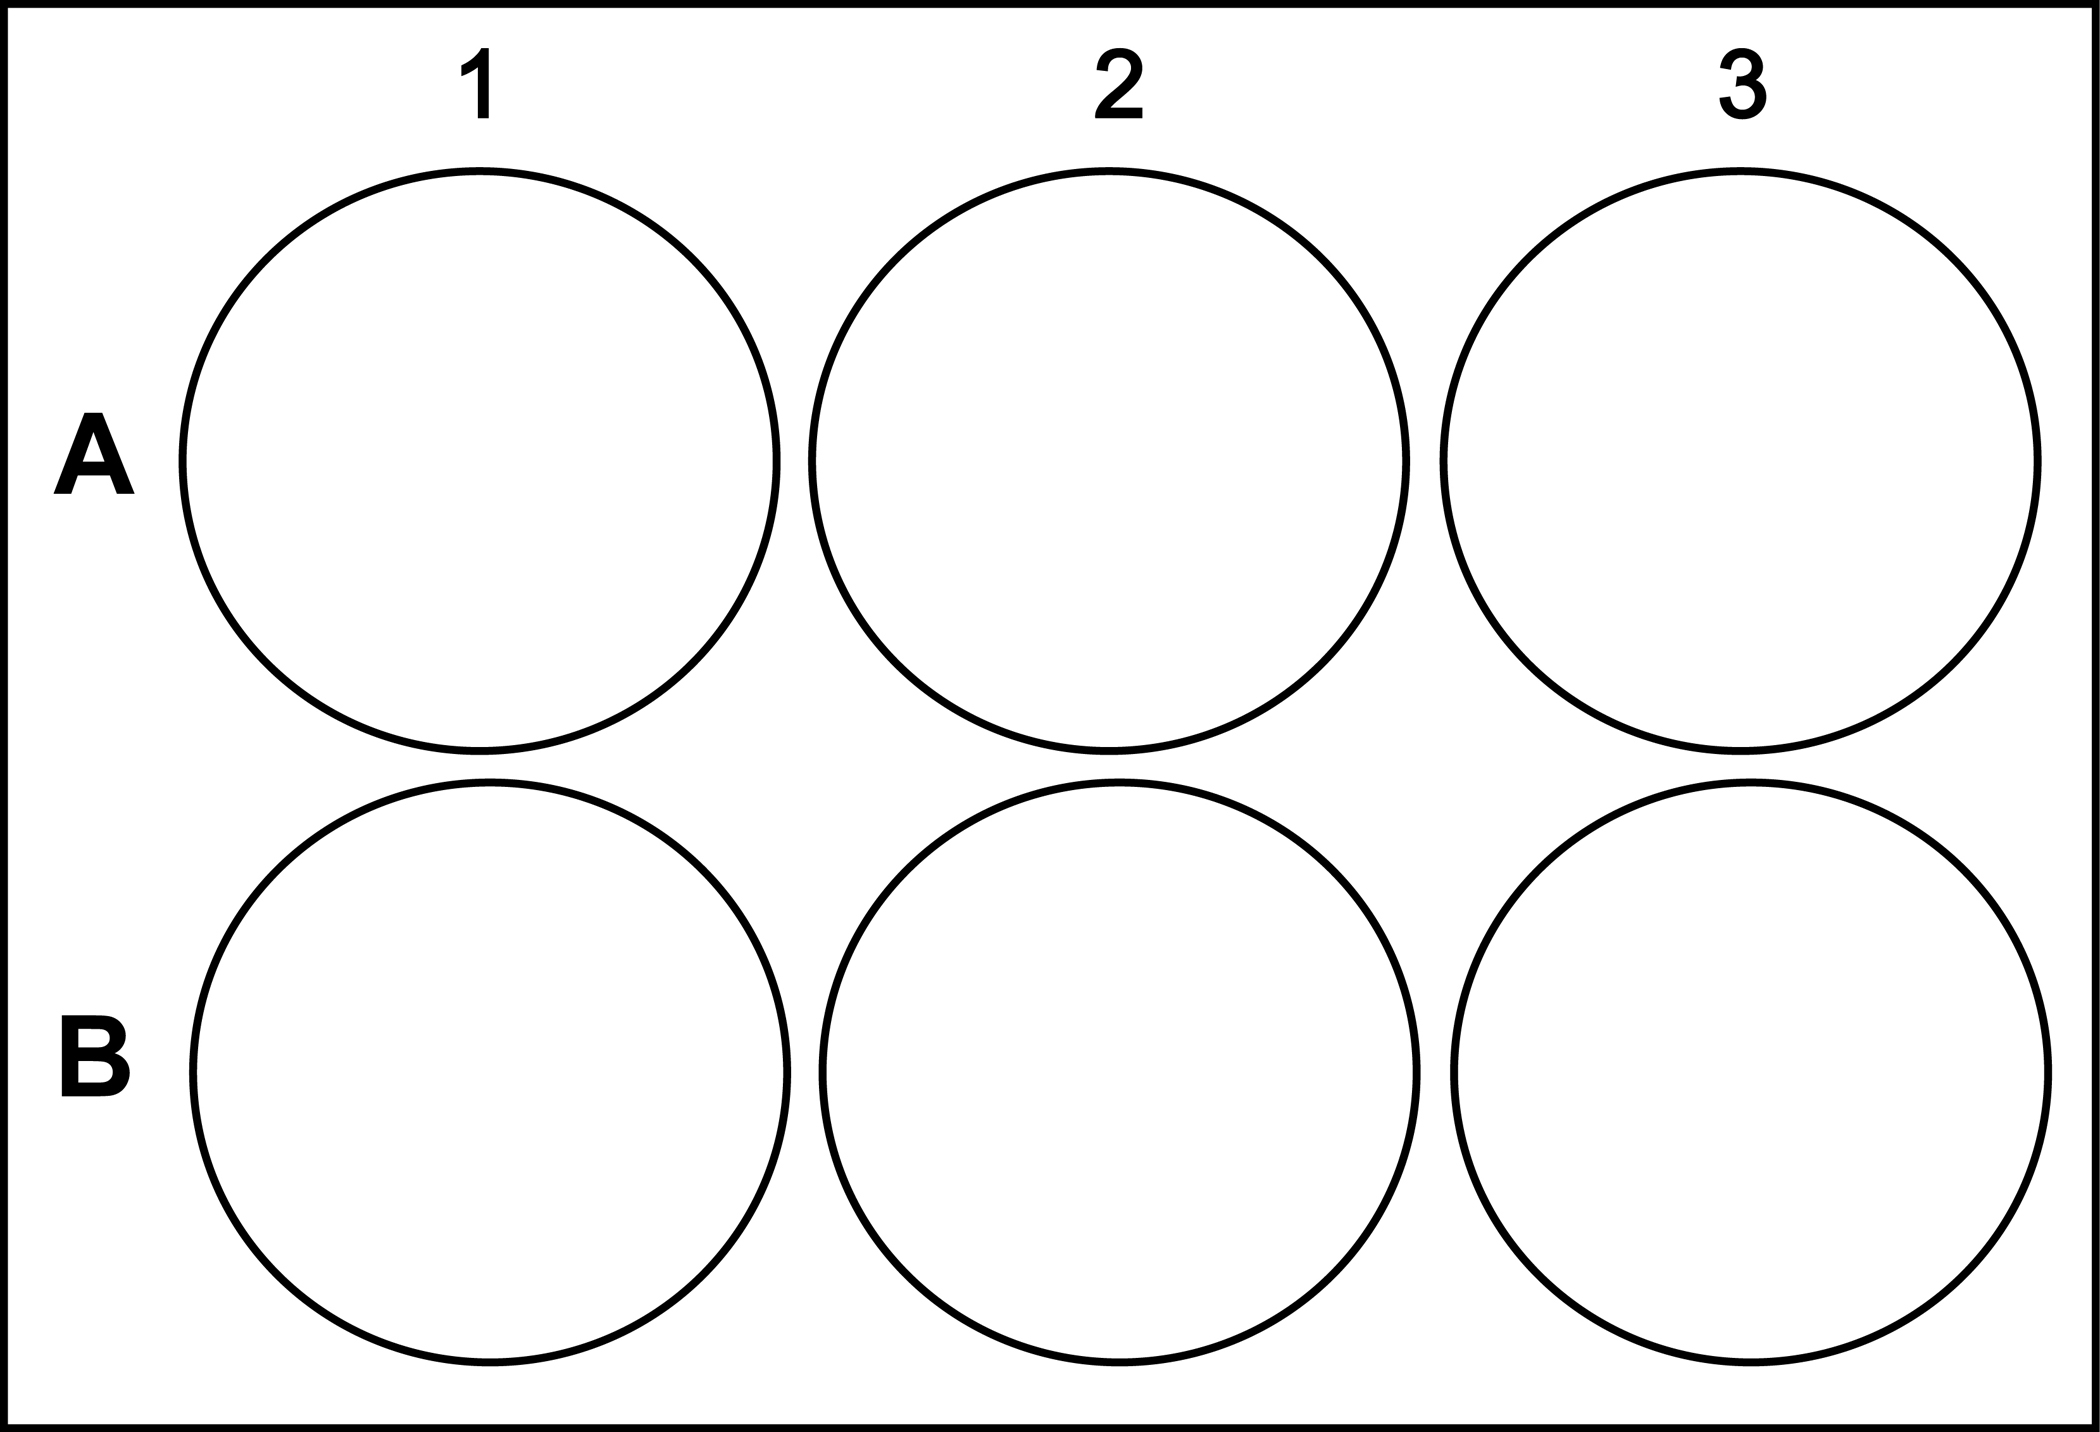

Crea un arreglo (e.g., `pozos`) con 6 strings que contenga la etiqueta de los `pozos` (a1, a2, a3, b1, b2 y b3). Pista ctrl + f y busca "*array1*".

wells = {'a1'; 'a2'; 'a3'; 'b1'; 'b2'; 'b3'};

Crea una matriz (`A1`) de 6x5 (muestras x organismos) con los pares de base identificados en cada muestra con los datos que están en la siguiente matriz en kilobase (kb):

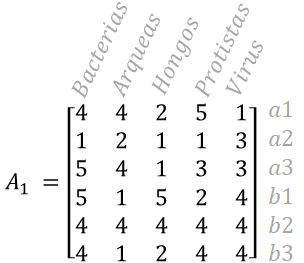

Pista ctrl + f y busca "*M1 = [*".

A1 = [4 4 2 5 1; 1 2 1 1 3; 5 4 1 3 3; 5 1 5 2 4 ; 4 4 4 4 4; 4 1 2 4 4];

La siguiente muestra llego por replicado (`M1` y `M2`). Necesitas definir `M1` y `M2 `y sacar el promedio de la expresión entre ambas muestras (`A2`). Pista ctrl + f y busca "*M7*".

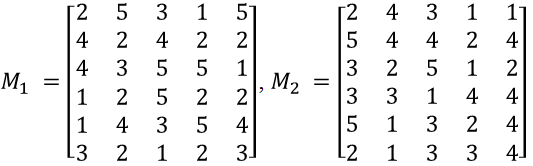

M1 = [2 5 3 1 5; 4 2 4 2 2; 4 3 5 5 1; 1 2 5 2 2; 1 4 3 5 4; 3 2 1 2 3];
M2 = [2 4 3 1 1; 5 4 4 2 4; 3 2 5 1 2; 3 3 1 4 4; 5 1 3 2 4; 2 1 3 3 4];
A2 = (M1 + M2) / 2;

Ahora te llegaron 4 muestras más  (`A3`, `A4`, `A5`, `A6`), utiliza la función "`randi"` para inventarte las kb encontradas en cada muestra y su rango sea de entre 1-5kb. Revisa la ayuda de MATLAB ya sea online o en la parte superior derecha (help `randi` no sirve de mucho XD).

A3 = randi(5, 6, 5);
A4 = randi(5, 6, 5);
A5 = randi(5, 6, 5);
A6 = randi(5, 6, 5);

### Paso 2 - Hacer un script que resuelva la **ecuación **$A\cdot x=b$

Ya que queremos la muestra más que tenga más pares de bases de organismos específicos necesitamos:

- Definir `x` como: 

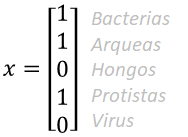

(recuerda que no es lo mismo $m\cdot n$ que $n\cdot m$)

- Encontrar $b$ usando `A1 en `$A\cdot x=b$

- Encontrar la muestra más interesante para el laboratorio, usar la ayuda de `max`, `find` y el doble signo de igualdad `==`.

% Definir x
x = [1; 1; 0; 1; 0];
% Encontrar b
b = A1 * x;
% Encontrar el valor mas grande
bestWellIdx = find(b == max(b));

### Paso 3 - Hacer una funcion que imprima los resultados

- Guardar el arreglo `wells` en la estructura `experimentalData; `Pista ctrl + f y busca `"`*sa1*`"`

- Guardar las matrices `A1`, `A2`, `A3`, `A4`, `A5` y `A6` en el arreglo estructura `experimentalData`

- Guardar el vector `x` indicando nuestros organismos de interés en la estructura `experimentalData`

- Hacer una función de la forma "wellSelectedPerSample` = findTheBestSample(experimentalData, printLevel)`"; Pista usar `open linearEquationsSolver`

- Incluir descripción de la función

- `wellSelectedPerSample` señala el pozo que se debe de utilizar por muestra (pozo: $a_n$ o $b_n$; Paso 2 y lo ultimo de la *Seccion 02. Operación entre vectores y matrices*).

- `printLevel` igual 1 imprime una tabla que indique la expresión combinada de los organismosde interés por cada muestra en cada pozo y algunos mensajes del progreso de la función.

- `printLevel` igual 2 imprime una figura señalando la expresión combinada de los organismos de interés por muestra ($b$ en $A\cdot x=b$; usar `subplot` y `heatmap`). Reorganizar $b$ de $1\times 6$ a $3\times 2$ para representar una caja de cultivo.

experimentalData.wells = wells;
experimentalData.samples.A1 = A1;
experimentalData.samples.A2 = A2;
experimentalData.samples.A3 = A3;
experimentalData.samples.A4 = A4;
experimentalData.samples.A5 = A5;
experimentalData.samples.A6 = A6;
experimentalData.x = x;
printLevel = 0;
wellSelectedPerSample = findTheBestSample(experimentalData, printLevel);
printLevel = 1;
wellSelectedPerSample = findTheBestSample(experimentalData, printLevel);

Comenzando...
 
Analisis terminado!
 


wellSelectedPerSample = 6×1 cell array
    {'Mejor pozo en muestra.  A1: a1'      }
    {'Mejor pozo en muestra.  A2: a2'      }
    {'Mejor pozo en muestra.  A3: a2'      }
    {'Mejor pozo en muestra.  A4: a2a3'    }
    {'Mejor pozo en muestra.  A5: b2'      }
    {'Mejor pozo en muestra.  A6: a1a2b2b3'}


Expresion de organismos de interes por muestra:


t = 6×7 table
    Pozos     A1    A2     A3    A4    A5    A6
    ______    __    ___    __    __    __    __

    {'a1'}    13    7.5     8     6     6    10
    {'a2'}     4    9.5    12    10    10    10
    {'a3'}    12      9    11    10    10     8
    {'b1'}     8    7.5    11     7     7     7
    {'b2'}    12      9     7     8    14    10
    {'b3'}     9    6.5     7     4    11    10


Comenzando...
 
Analisis terminado!
 


wellSelectedPerSample = 6×1 cell array
    {'Mejor pozo en muestra.  A1: a1'      }
    {'Mejor pozo en muestra.  A2: a2'      }
    {'Mejor pozo en muestra.  A3: a2'      }
    {'Mejor pozo en muestra.  A4: a2a3'    }
    {'Mejor pozo en muestra.  A5: b2'      }
    {'Mejor pozo en muestra.  A6: a1a2b2b3'}


Expresion de organismos de interes por muestra:


t = 6×7 table
    Pozos     A1    A2     A3    A4    A5    A6
    ______    __    ___    __    __    __    __

    {'a1'}    13    7.5     8     6     6    10
    {'a2'}     4    9.5    12    10    10    10
    {'a3'}    12      9    11    10    10     8
    {'b1'}     8    7.5    11     7     7     7
    {'b2'}    12      9     7     8    14    10
    {'b3'}     9    6.5     7     4    11    10


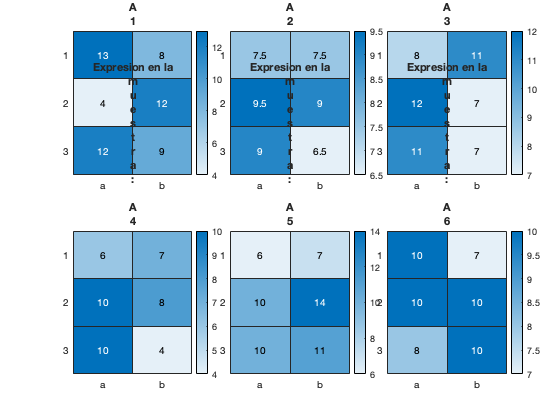

printLevel = 2;
wellSelectedPerSample = findTheBestSample(experimentalData, printLevel);